# Example 1.2: Equilibrium (Gibbs) Reactor

Note: this script creates the reactor data of Example 1.2 (Section 1.1) of **Statistics for Chemical Engineers**; the Gibbs reactor is used throughout the book. Victor Z UW-Madison, 2020 data for gibbs reactor problem

clc; clear all; close all hidden

## Reactor conversion data

Note: conversion of the reaction CO + 2H2 [-](http://-) CH3OH at different pressures and temperatures. create data set

load ('./Data/gibbs_hightemp_class.dat')
datahigh=gibbs_hightemp_class;
load ('./Data/gibbs_lowtemp_class.dat')
datalow=gibbs_lowtemp_class;
data=[datahigh;datalow];
datan=data;
n=length(datan);

## Add noise

Note: measurements are noisy, which partly hides the pattern (the unknown part of the system). corrupt data with noise to hide pattern

rng(1); % For reproducibility 
x1 = datan(:,2)+randn(n,1)*0.1; % pressure 
x2 = datan(:,3)+randn(n,1)*0.1; % conversion
y=datan(:,1)+randn(n,1)*0.1;    % temperature

## Visualize

Note: conversion tends to increase with pressure and to decrease with temperature, but the trend is blurred by the noise. visualize the data in 2d

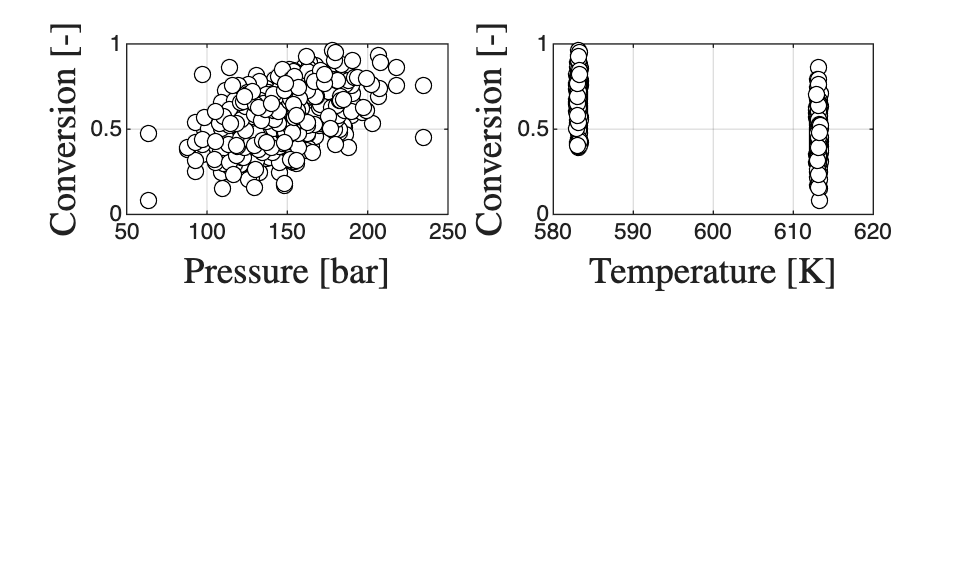

figure(1)

subplot(2,2,1)
scatter(x1,x2,'MarkerFaceColor','w','MarkerEdgeColor','black')
grid on
xlabel('$\textrm{Pressure [bar]}$','Interpreter','latex','FontSize',14)
ylabel('$\textrm{Conversion [-]}$','Interpreter','latex','FontSize',14)
box on

subplot(2,2,2)
scatter(y,x2,'MarkerFaceColor','w','MarkerEdgeColor','black')
grid on
xlabel('$\textrm{Temperature [K]}$','Interpreter','latex','FontSize',14)
ylabel('$\textrm{Conversion [-]}$','Interpreter','latex','FontSize',14)
box on

print -depsc ch1_gibbs_data.eps

## Note

As discussed in the book, data reveal trends but cannot explain them alone; a model (thermodynamics) helps, and some aspects of the system remain unknown, so new experiments may still be needed.